**Load paths**

start_toolkit

### **How pressure changes during fire-fighting?**

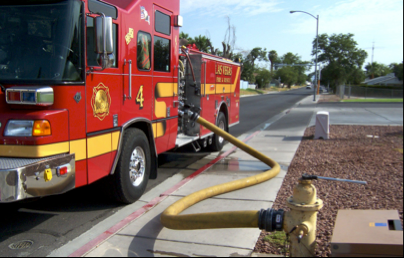

When flow is increased within the network, e.g., due to fire-fighting, the pressure changes near that location. Investigate this change, at node '32'.

G = epanet('Net1.inp');
nodeID = {'32'};
figure
G.plot('highlightnode', nodeID)

**During fire-fighting, the base demand may increase up to x5. Will there be sufficient pressure?**

idx = G.getNodeIndex(nodeID)
bd = G.getNodeBaseDemands{1}(idx)

demand_multi = 8 % demand multiplicator

d32 = bd *(1:demand_multi) % create the different demands
 
p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

**Plot demand vs pressure**

figure 
plot(d32, p32min,'x-')
grid on
xlabel('Base demand (m^3/h)')
ylabel('Pressure (psi)')

How about those negative pressures?

**Pressure Driven Simulations**

When the pressure is low, it should approximate zero. This is not the default mode of operation in EPANET. However, it's easy to set it up:

type = 'PDA';
pmin = 0;
preq = 0.1;
pexp = 0.5;
G.setDemandModel(type, pmin, preq, pexp)

Let's try this again

demand_multi = 10 % demand multiplicator
d32 = bd *(1:demand_multi) % create the different demands

p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

figure 
plot(d32, p32min,'x-')
grid on
